# CNN Classifier

clear all;
clc;

## 1. Load Data

%Load the digit sample data as an image datastore.
%The imageDatastore function automatically labels the images based on folder names.

digitDatasetPath = fullfile('C:\Users\goode\Downloads\Face-Images\Face Images\OurFaces');
untrainedFacePath = fullfile('C:\Users\goode\Downloads\Face-Images\Face Images\Resized Final Training Images\face7');


imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imdsUntrainedFace = imageDatastore(untrainedFacePath, ...
        'IncludeSubfolders',true, ...
        'LabelSource','foldernames');

## 2. Divide the data into training and validation data sets

%Divide the data into training and validation data sets, so that
%each category in the training set contains 750 images, and
%the validation set contains the remaining images from each label.
%splitEachLabel splits the image datastore into two new datastores for
%training and validation.
numLabels = countEachLabel(imds)

numLabels = 5×2 table
       Label        Count
    ____________    _____

    facesAndrew      497 
    facesAsh         501 
    facesAshwin      496 
    facesRory        499 
    unknownFaces      77 


numTrainFiles = 50;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## 3. Define the CNN Architecture

%Define the convolutional neural network architecture.
%Specify the size of the images in the input layer of the network and
%the number of classes in the fully connected layer before
%the classification layer. Each image is 28-by-28-by-1
%pixels and there are 10 classes.

inputSize = [200 200 3];
numClasses = 5;
layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(200,120)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];
%For more information about deep learning layers, see List of Deep Learning Layers.

## 4. Specify the training options and train the CNN classifier.

%By default, trainNetwork uses a GPU if one is available, otherwise,
%it uses a CPU. Training on a GPU requires Parallel Computing Toolbox™
%and a supported GPU device. For information on supported devices, see
%GPU Support by Release (Parallel Computing Toolbox). You can also
%specify the execution environment by using the 'ExecutionEnvironment'
%name-value pair argument of trainingOptions.

options = trainingOptions('sgdm', ...
    'MaxEpochs',64, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

%For more information about training options, see
%Set Up Parameters and Train Convolutional Neural Network.

## 5. Train the CNN classifier

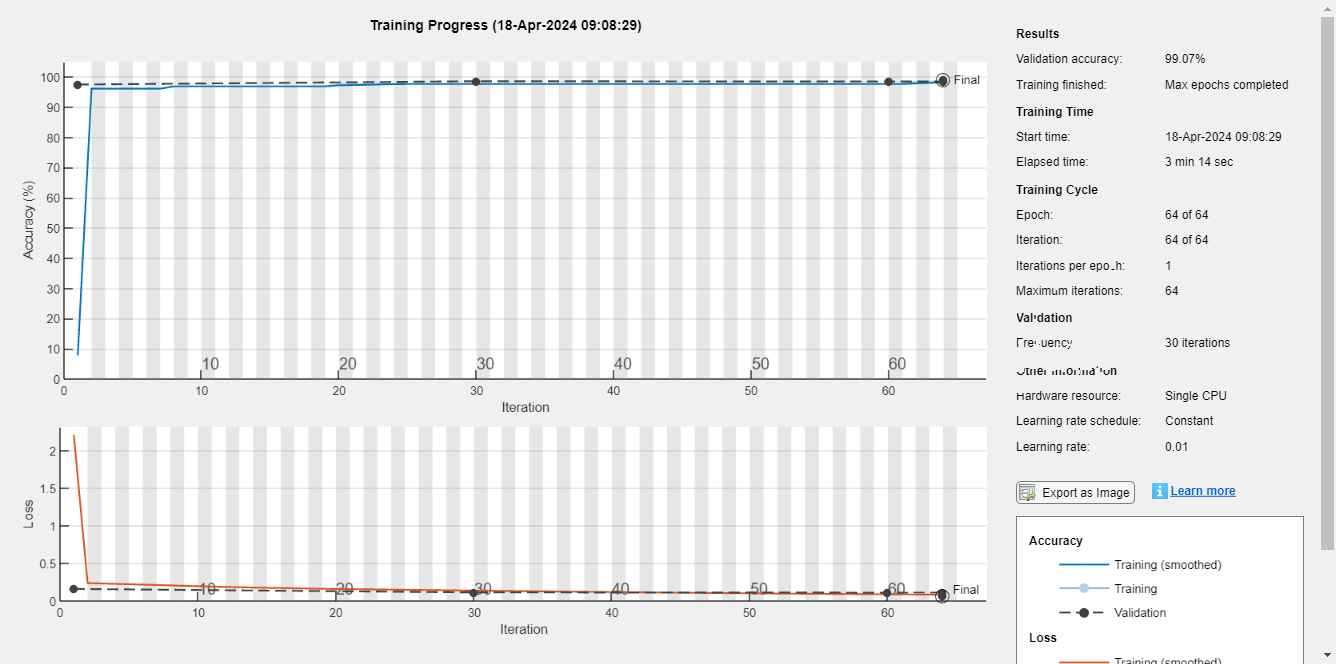

%Train the network using the following command.
%Observe the training progress displayed on training plots.

net = trainNetwork(imdsTrain,layers,options);

## 6. Test the trained CNN classifier

%Classify the validation data using:
YPred = classify(net,imdsValidation);

%YPred contains the predicted labels, the “actual “ground truth labels
%are stored in imdsValidation.Labels

%Calculate and display the CNN accuracy as the percentage of the correctly
%predicted labels.
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9907

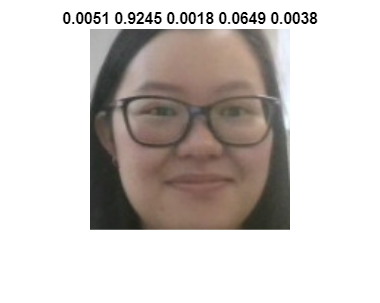

[Y,TestPrediction] = classify(net, imdsUntrainedFace);
predictionUntrained = predict(net, imdsUntrainedFace);

figure 
i = 1;
titleString = strcat(num2str(round(predictionUntrained(i,1),4)), " ", num2str(round(predictionUntrained(i,2),4)), " ", num2str(round(predictionUntrained(i,3),4)), " ", num2str(round(predictionUntrained(i,4),4)), " ", num2str(round(predictionUntrained(i,5),4)));
imshow(imdsUntrainedFace.Files{i});
title(titleString)

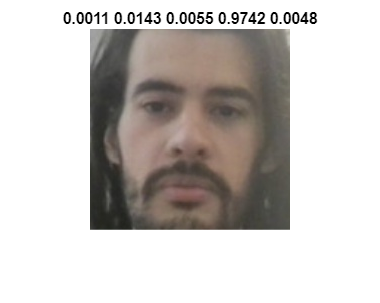

figure 
i = 2;
titleString = strcat(num2str(round(predictionUntrained(i,1),4)), " ", num2str(round(predictionUntrained(i,2),4)), " ", num2str(round(predictionUntrained(i,3),4)), " ", num2str(round(predictionUntrained(i,4),4)), " ", num2str(round(predictionUntrained(i,5),4)));
imshow(imdsUntrainedFace.Files{i});
title(titleString)

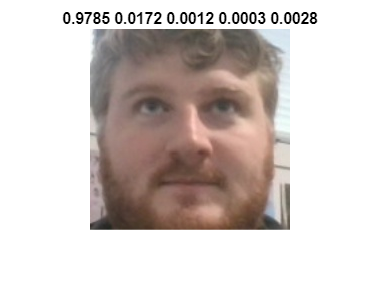


figure 
i = 3;
titleString = strcat(num2str(round(predictionUntrained(i,1),4)), " ", num2str(round(predictionUntrained(i,2),4)), " ", num2str(round(predictionUntrained(i,3),4)), " ", num2str(round(predictionUntrained(i,4),4)), " ", num2str(round(predictionUntrained(i,5),4)));
imshow(imdsUntrainedFace.Files{i});
title(titleString)

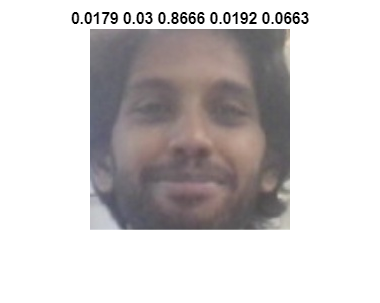


figure 
i = 4;
titleString = strcat(num2str(round(predictionUntrained(i,1),4)), " ", num2str(round(predictionUntrained(i,2),4)), " ", num2str(round(predictionUntrained(i,3),4)), " ", num2str(round(predictionUntrained(i,4),4)), " ", num2str(round(predictionUntrained(i,5),4)));
imshow(imdsUntrainedFace.Files{i});
title(titleString)

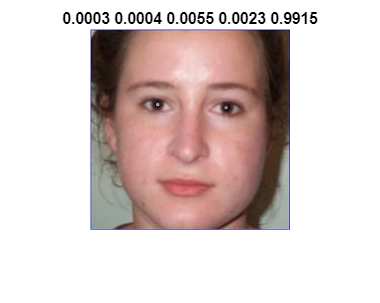


figure 
i = 5;
titleString = strcat(num2str(round(predictionUntrained(i,1),4)), " ", num2str(round(predictionUntrained(i,2),4)), " ", num2str(round(predictionUntrained(i,3),4)), " ", num2str(round(predictionUntrained(i,4),4)), " ", num2str(round(predictionUntrained(i,5),4)));
imshow(imdsUntrainedFace.Files{i});
title(titleString)

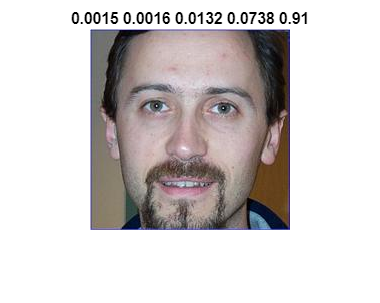


figure 
i = 6;
titleString = strcat(num2str(round(predictionUntrained(i,1),4)), " ", num2str(round(predictionUntrained(i,2),4)), " ", num2str(round(predictionUntrained(i,3),4)), " ", num2str(round(predictionUntrained(i,4),4)), " ", num2str(round(predictionUntrained(i,5),4)));
imshow(imdsUntrainedFace.Files{i});
title(titleString)

## CONVERT IMAGES to 200x200 px

trainingDataLocation = 'C:\Users\goode\Downloads\Face-Images\Face Images\Final Training Images';
locationToWriteResizedImages = 'C:\Users\goode\Downloads\Face-Images\Face Images\Resized Final Training Images';
digitDatasetPath = fullfile(trainingDataLocation);
folders = dir(digitDatasetPath);
subFolderNames = {folders(4:end).name};
for k = 1 : length(subFolderNames)
      name = subFolderNames{k}
      folderPath = strcat(trainingDataLocation,"\",name)
      folderImages = fullfile(folderPath)
      faceFolder = dir(folderImages)
      subFaceFolderNames = {faceFolder(3:end).name};
      for j = 1 : length(subFaceFolderNames)
          pictureName = subFaceFolderNames{j}
          picturePath = strcat(folderPath,"\",pictureName)
          picture = imread(picturePath)
          resizedImage = imresize(picture,[200 200]);
          imageWritePath = strcat(locationToWriteResizedImages,"\",name,"\",pictureName)
          imwrite(resizedImage, imageWritePath);
      end
end